# 1

clear;clc

%(a)
rng(13);
Qnum = 40;
student = 5000;

%(b)
p = 0.35 + (0.95-0.35)*rand(1,Qnum);
disp('문항별 정답확률 p_i')

문항별 정답확률 p_i


disp(p)

    0.8166    0.4925    0.8446    0.9294    0.9336    0.6221    0.7154    0.8153    0.7350    0.7832    0.3710    0.5291    0.3851    0.8642    0.5737    0.7579    0.5038    0.5585    0.3556    0.5650    0.9195    0.4807    0.5416    0.9007    0.3691    0.3891    0.7279    0.8743    0.3552    0.7979    0.8377    0.3954    0.7439    0.6556    0.6379    0.9233    0.3500    0.4982    0.7773    0.5447




%(c)
correct = rand(student, Qnum) < p;
% true  = 정답
% false = 오답

% (d) 각 학생의 총점, 평균점수, 표준편차 계산
score = sum(correct, 2);   % 각 학생의 총점, 5000 x 1 벡터

meanScore = mean(score);   % 평균점수
stdScore = std(score);     % 표준편차

fprintf('평균 점수 = %.2f점\n', meanScore)

평균 점수 = 25.84점


fprintf('표준편차 = %.2f점\n', stdScore)

표준편차 = 2.81점


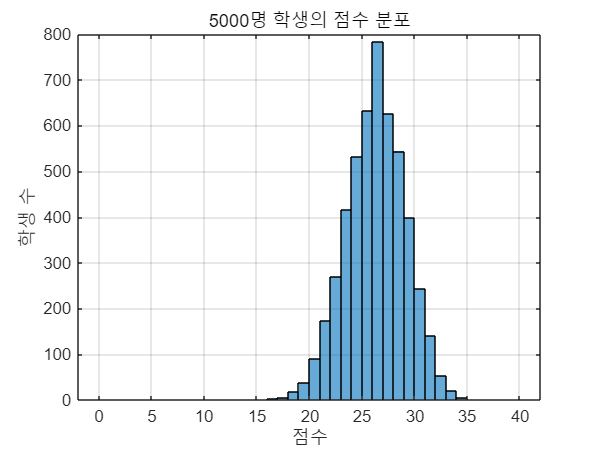


% (e) 점수 histogram 및 평균점수 이상 학생 비율 계산
figure
histogram(score, 0:1:40)
grid on
title('5000명 학생의 점수 분포')
xlabel('점수')
ylabel('학생 수')


ratioAboveMean = sum(score >= meanScore) / student;

fprintf('평균점수 이상인 학생의 비율 = %.4f\n', ratioAboveMean)

평균점수 이상인 학생의 비율 = 0.5640


fprintf('평균점수 이상인 학생의 비율 = %.2f%%\n', ratioAboveMean * 100)

평균점수 이상인 학생의 비율 = 56.40%


# 2

clear;clc

%(a)
boxN = 10000;
prN = 20;
weight =  100 + 4 * randn(boxN,prN);

%(b)
box_meanWeight = sum(weight,2)/prN;

%(c)
fail = (box_meanWeight < 98) | (box_meanWeight > 102);

%(d)
failRate = sum(fail)/boxN

failRate = 0.0236



fprintf('불합격 상자 수 = %d개\n', sum(fail))

불합격 상자 수 = 236개


fprintf('불합격률 = %.4f\n', failRate)

불합격률 = 0.0236


fprintf('불합격률 = %.2f%%\n', failRate * 100)

불합격률 = 2.36%


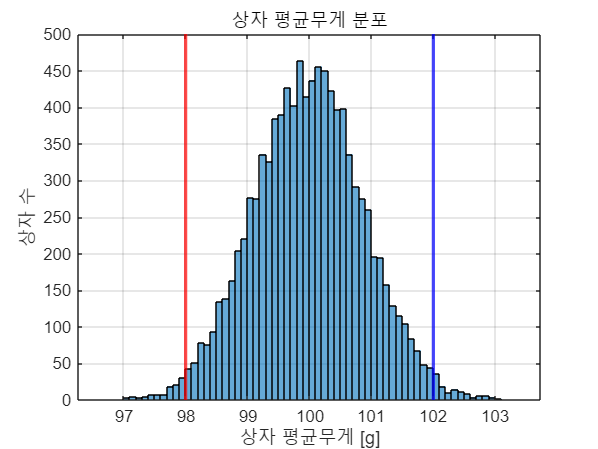


%(e)
figure;
histogram(box_meanWeight)
grid on
title('상자 평균무게 분포')
xlabel('상자 평균무게 [g]')
ylabel('상자 수')

hold on
xline(98, 'LineWidth', 2, 'Color','r')
xline(102, 'LineWidth', 2, 'Color', 'b')
hold off

# 3

clear;clc

A = 1.8;
threshold = 1.2;
n = 100000;

%(a)
N = randn(n,1);

%(b)
S = A + N;

%(c)
sucess = S>=threshold;

%(d)
sucessRate = sum(sucess)./n;
fprintf('감지 성공률 = %.4f\n', sucessRate)

감지 성공률 = 0.7251


fprintf('감지 성공률 = %.2f%%\n', sucessRate * 100)

감지 성공률 = 72.51%


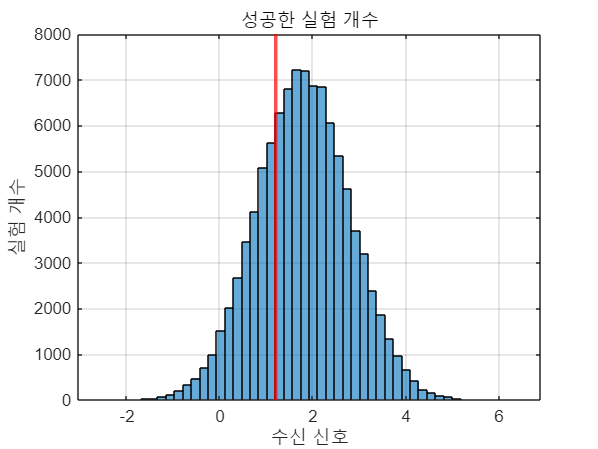


%(e)
figure;
histogram(S,50);
title('성공한 실험 개수')
xlabel('수신 신호')
ylabel('실험 개수')
hold on
grid on

xline(1.2,'LineWidth',2,'Color','r')

# 4

clear; clc;

%% 조건 설정
days = 365;
lambda = 180;

mu_time = 6;
sigma_time = 2;

limit_time = 1200;

%% (a) poissrnd를 이용하여 365일의 주문 수 생성
order_count = poissrnd(lambda, days, 1);

%% (b) 날짜별 총 처리시간 계산
total_time = zeros(days, 1);

for d = 1:days
    n_order = order_count(d);

    process_time = mu_time + sigma_time * randn(n_order, 1);

    process_time(process_time < 0) = 0;

    total_time(d) = sum(process_time);
end

%% (c) 하루 총 처리시간이 1200분을 초과하는 날의 비율
over_limit = total_time > limit_time;

over_ratio = sum(over_limit) / days;

fprintf('1200분 초과 비율 = %.4f\n', over_ratio);

1200분 초과 비율 = 0.0822


fprintf('1200분 초과 비율 = %.2f%%\n', over_ratio * 100);

1200분 초과 비율 = 8.22%


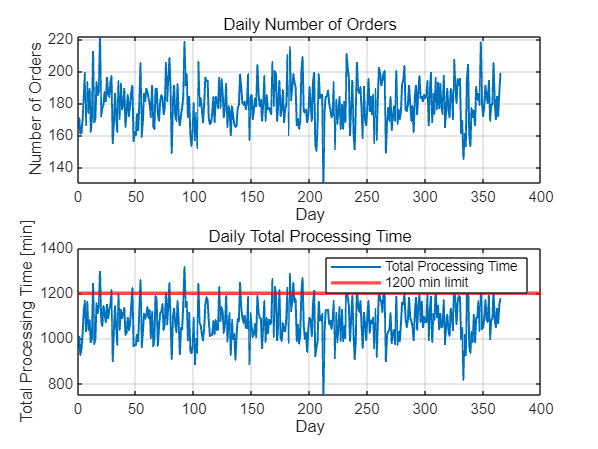


%% (d) 하루 주문수와 하루 총 처리시간 그래프
figure;

subplot(2,1,1);
plot(1:days, order_count, 'LineWidth', 1.2);
grid on;
title('Daily Number of Orders');
xlabel('Day');
ylabel('Number of Orders');

subplot(2,1,2);
plot(1:days, total_time, 'LineWidth', 1.2);
grid on;
hold on;
yline(limit_time, 'r', 'LineWidth', 2);
title('Daily Total Processing Time');
xlabel('Day');
ylabel('Total Processing Time [min]');
legend('Total Processing Time', '1200 min limit');

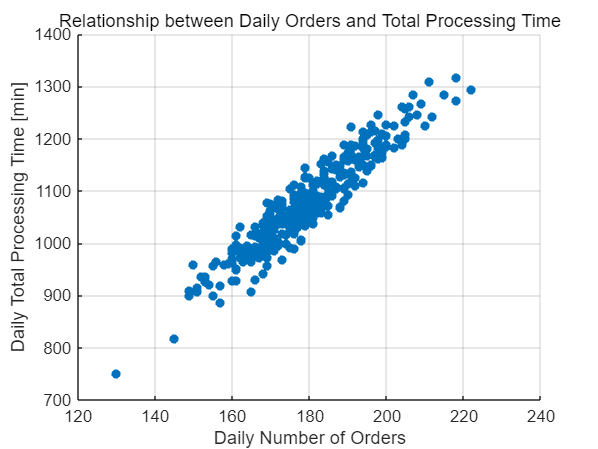


%% (e) 주문수와 총 처리시간 scatterplot
figure;
scatter(order_count, total_time, 30, 'filled');
grid on;
title('Relationship between Daily Orders and Total Processing Time');
xlabel('Daily Number of Orders');
ylabel('Daily Total Processing Time [min]');

# 5

clear; clc;

%% 조건 설정
true_temp = 25;      % 실제 온도
sigma = 0.8;         % 센서 측정 오차의 표준편차
n_repeat = 10000;    % 반복 측정 횟수
n_sensor = 30;       % 센서 개수

%% (a) 10000 x 30 크기의 측정값 행렬 생성
% 측정값 = 실제온도 + 측정오차
% 측정오차 ~ N(0, 0.8^2)

measurements = true_temp + sigma * randn(n_repeat, n_sensor);

%% (b) 각 반복 측정에서 30개 센서의 평균값 계산
mean_temp = mean(measurements, 2);

%% (c) 평균 측정값이 24.7 이상 25.3 이하인 사건 정의
in_range = mean_temp >= 24.7 & mean_temp <= 25.3;

%% (d) 해당 사건의 확률 추정
prob = sum(in_range) / n_repeat;

fprintf('30개 센서 평균값이 24.7 이상 25.3 이하일 확률 = %.4f\n', prob);

30개 센서 평균값이 24.7 이상 25.3 이하일 확률 = 0.9580


fprintf('확률 = %.2f%%\n', prob * 100);

확률 = 95.80%


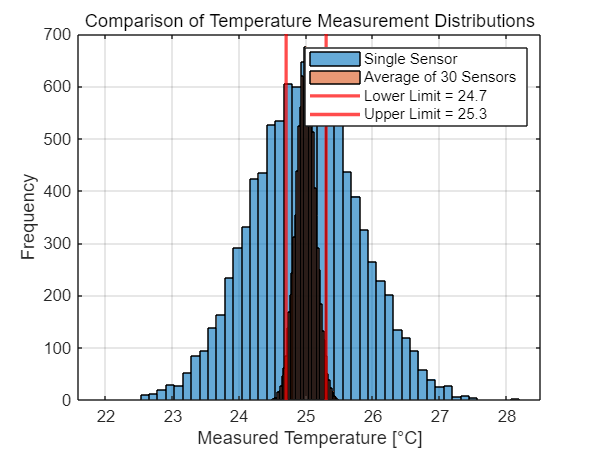


%% (e) 센서 1개만 사용할 때와 30개 평균을 사용할 때의 분포 비교

sensor_one = measurements(:, 1);   % 센서 1개만 사용한 측정값

figure;

histogram(sensor_one, 50);
hold on;
histogram(mean_temp, 50);

xline(24.7, 'r', 'LineWidth', 2);
xline(25.3, 'r', 'LineWidth', 2);

grid on;
title('Comparison of Temperature Measurement Distributions');
xlabel('Measured Temperature [°C]');
ylabel('Frequency');

legend('Single Sensor', 'Average of 30 Sensors', ...
       'Lower Limit = 24.7', 'Upper Limit = 25.3');

# 6

clear; clc;

%% 조건 설정
n_path = 5000;      % 자산 경로 개수
n_day = 60;         % 관찰 기간
mu = 0.0008;        % 하루 평균 수익률
sigma = 0.015;      % 하루 수익률 표준편차
initial_asset = 100;

%% (a) 5000 x 60 크기의 일별 수익률 행렬 생성
daily_return = mu + sigma * randn(n_path, n_day);

%% (b) 각 경로에 대해 누적 자산가치 계산
% 하루 뒤 자산 = 이전 자산 * (1 + r)
asset_path = initial_asset * cumprod(1 + daily_return, 2);

%% (c) 마지막 날 자산가치의 평균, 최솟값, 최댓값 출력
final_asset = asset_path(:, end);

mean_final = mean(final_asset);
min_final = min(final_asset);
max_final = max(final_asset);

fprintf('마지막 날 자산가치 평균 = %.4f\n', mean_final);

마지막 날 자산가치 평균 = 105.2004


fprintf('마지막 날 자산가치 최솟값 = %.4f\n', min_final);

마지막 날 자산가치 최솟값 = 67.7548


fprintf('마지막 날 자산가치 최댓값 = %.4f\n', max_final);

마지막 날 자산가치 최댓값 = 160.1223



%% (d) 마지막 날 자산가치가 100보다 작을 확률 추정
loss_event = final_asset < initial_asset;

loss_prob = sum(loss_event) / n_path;

fprintf('마지막 날 자산가치가 100보다 작을 확률 = %.4f\n', loss_prob);

마지막 날 자산가치가 100보다 작을 확률 = 0.3524


fprintf('확률 = %.2f%%\n', loss_prob * 100);

확률 = 35.24%


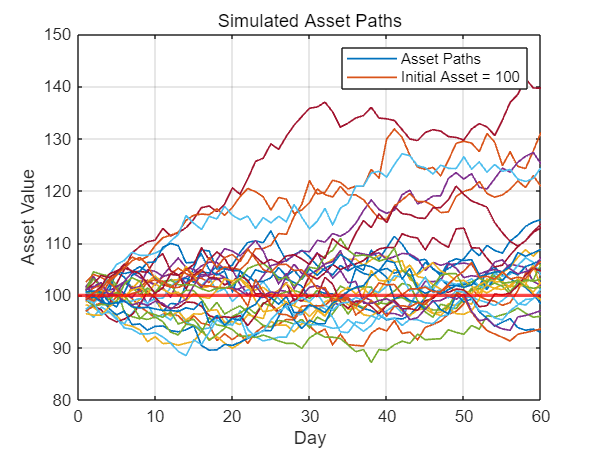


%% (e) 임의로 선택한 30개 경로를 하나의 그래프에 표시
idx = randperm(n_path, 30);

figure;
plot(1:n_day, asset_path(idx, :)', 'LineWidth', 1.0);
grid on;

title('Simulated Asset Paths');
xlabel('Day');
ylabel('Asset Value');

yline(initial_asset, 'r', 'LineWidth', 2);
legend('Asset Paths', 'Initial Asset = 100');

# 7

clear; clc;

%% 조건 설정
n_patient = 300;       % 환자 수
mean_arrival = 8;      % 평균 도착 간격 [분]

mu_service = 10;       % 평균 진료 시간 [분]
sigma_service = 3;     % 진료 시간 표준편차 [분]

%% (a) 환자 간 도착 간격 300개 생성 후 도착 시각 계산
inter_arrival = exprnd(mean_arrival, n_patient, 1);

arrival_time = cumsum(inter_arrival);

%% (b) 각 환자의 진료 시간 생성
service_time = mu_service + sigma_service * randn(n_patient, 1);

% 음수 진료 시간은 1분으로 대체
service_time(service_time < 0) = 1;

%% (c) 각 환자의 진료 시작 시각과 종료 시각 계산
start_time = zeros(n_patient, 1);
end_time = zeros(n_patient, 1);

% 첫 번째 환자
start_time(1) = arrival_time(1);
end_time(1) = start_time(1) + service_time(1);

% 두 번째 환자부터 300번째 환자까지
for i = 2:n_patient
    start_time(i) = max(arrival_time(i), end_time(i-1));
    end_time(i) = start_time(i) + service_time(i);
end

%% (d) 각 환자의 대기시간 계산
waiting_time = start_time - arrival_time;

%% (e) 평균 대기시간, 최대 대기시간, 20분 초과 비율 출력
mean_wait = mean(waiting_time);
max_wait = max(waiting_time);

over_20 = waiting_time > 20;
over_20_ratio = sum(over_20) / n_patient;

fprintf('평균 대기시간 = %.4f분\n', mean_wait);

평균 대기시간 = 305.0979분


fprintf('최대 대기시간 = %.4f분\n', max_wait);

최대 대기시간 = 644.9070분


fprintf('대기시간이 20분을 초과하는 환자의 비율 = %.4f\n', over_20_ratio);

대기시간이 20분을 초과하는 환자의 비율 = 0.9900


fprintf('대기시간이 20분을 초과하는 환자의 비율 = %.2f%%\n', over_20_ratio * 100);

대기시간이 20분을 초과하는 환자의 비율 = 99.00%


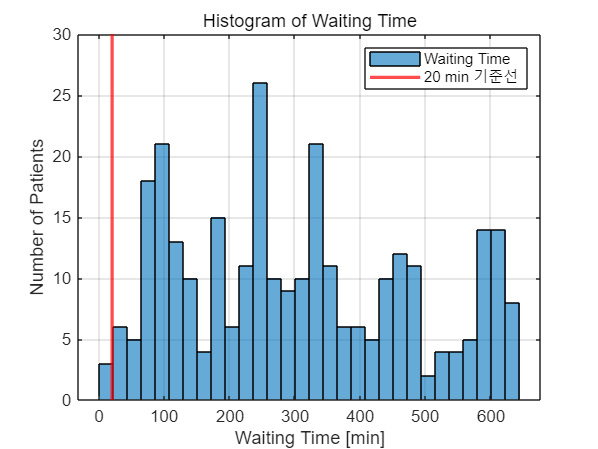


%% 대기시간 histogram
figure;
histogram(waiting_time, 30);
grid on;
hold on;

xline(20, 'r', 'LineWidth', 2);

title('Histogram of Waiting Time');
xlabel('Waiting Time [min]');
ylabel('Number of Patients');

legend('Waiting Time', '20 min 기준선');

# 8

clear; clc;

%% 조건 설정
n_trial = 100000;                 % 침입 상황 반복 횟수
p = [0.72, 0.81, 0.67, 0.90, 0.76]; % 각 모듈의 감지 확률

%% (a) 100000 x 5 크기의 난수 행렬 생성
R = rand(n_trial, 5);

%% (b) 각 열마다 다른 감지확률 pi가 적용되도록 logical matrix 생성
% R의 각 원소가 해당 모듈의 감지확률보다 작으면 감지 성공
detect_matrix = R < p;

%% (c) 각 실험에서 감지한 모듈 수 계산
detect_count = sum(detect_matrix, 2);

%% (d) 3개 이상 감지한 경우를 시스템 성공으로 정의하고 감지확률 계산
system_success = detect_count >= 3;

system_detect_prob = sum(system_success) / n_trial;

fprintf('시스템 감지 확률 = %.4f\n', system_detect_prob);

시스템 감지 확률 = 0.9243


fprintf('시스템 감지 확률 = %.2f%%\n', system_detect_prob * 100);

시스템 감지 확률 = 92.43%


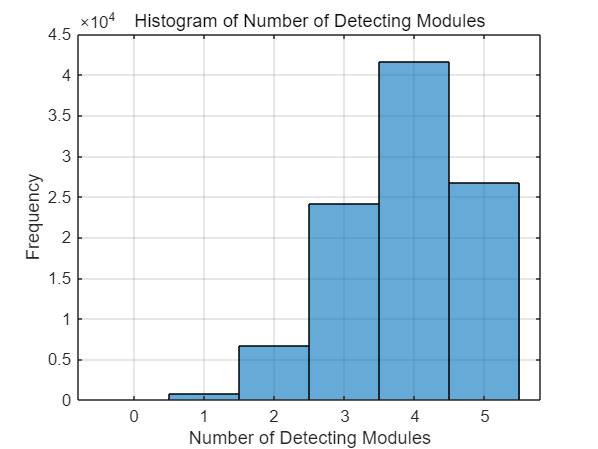


%% (e) 감지한 모듈 수 0,1,...,5에 대한 histogram
figure;
histogram(detect_count, -0.5:1:5.5);

grid on;
title('Histogram of Number of Detecting Modules');
xlabel('Number of Detecting Modules');
ylabel('Frequency');

xticks(0:5);

# 9

clear; clc;

%% 조건 설정
n_product = 50000;

p1 = 0.94;   % 1단계 통과 확률
p2 = 0.91;   % 2단계 통과 확률
p3 = 0.88;   % 3단계 통과 확률

%% (a) 1단계 통과 여부 logical vector 생성
pass1 = rand(n_product, 1) < p1;

%% (b) 1단계를 통과한 제품에 대해서만 2단계 통과 여부 생성
pass2 = false(n_product, 1);

idx1 = find(pass1);   % 1단계 통과 제품의 위치
pass2(idx1) = rand(length(idx1), 1) < p2;

%% (c) 2단계까지 통과한 제품에 대해서만 3단계 통과 여부 생성
pass3 = false(n_product, 1);

idx2 = find(pass2);   % 2단계까지 통과한 제품의 위치
pass3(idx2) = rand(length(idx2), 1) < p3;

%% (d) 최종 합격률 계산
final_pass = pass3;

final_pass_rate = sum(final_pass) / n_product;

fprintf('최종 합격률 = %.4f\n', final_pass_rate);

최종 합격률 = 0.7509


fprintf('최종 합격률 = %.2f%%\n', final_pass_rate * 100);

최종 합격률 = 75.09%


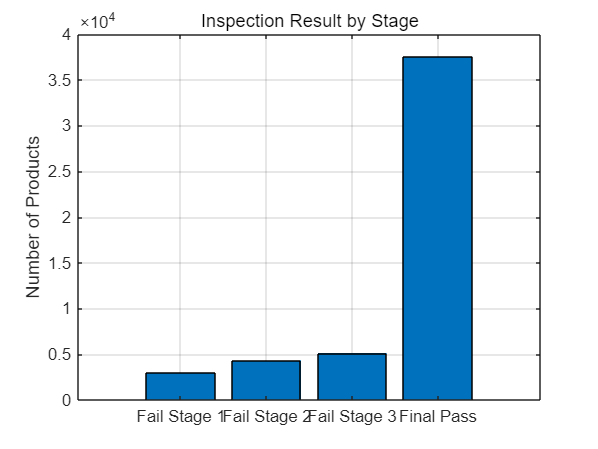


%% (e) 각 단계에서 탈락한 제품수와 최종 합격 제품수 계산
fail_stage1 = sum(~pass1);
fail_stage2 = sum(pass1 & ~pass2);
fail_stage3 = sum(pass2 & ~pass3);
final_pass_count = sum(final_pass);

count_result = [fail_stage1, fail_stage2, fail_stage3, final_pass_count];

%% bar graph
figure;
bar(count_result);
grid on;

title('Inspection Result by Stage');
ylabel('Number of Products');

xticks(1:4);
xticklabels({'Fail Stage 1', 'Fail Stage 2', 'Fail Stage 3', 'Final Pass'});


%% 결과 출력
fprintf('1단계 탈락 제품 수 = %d개\n', fail_stage1);

1단계 탈락 제품 수 = 2990개


fprintf('2단계 탈락 제품 수 = %d개\n', fail_stage2);

2단계 탈락 제품 수 = 4331개


fprintf('3단계 탈락 제품 수 = %d개\n', fail_stage3);

3단계 탈락 제품 수 = 5136개


fprintf('최종 합격 제품 수 = %d개\n', final_pass_count);

최종 합격 제품 수 = 37543개


# 10

clear; clc; close all;

%% 조건 설정
n_day = 10000;        % 시뮬레이션 일수
base_power = 500;     % 기본 전력 사용량

sigma_load = 35;      % 서버 부하 변동 표준편차

extra_cooling = 120;  % 냉각장치 과부하 시 추가 전력
p_overload = 0.12;    % 냉각장치 과부하 발생 확률

limit_power = 650;    % 기준 전력 사용량

%% (a) 서버 부하 변동을 randn으로 생성
server_load = sigma_load * randn(n_day, 1);

%% (b) 냉각장치 과부하 여부를 rand와 logical condition으로 생성
cooling_overload = rand(n_day, 1) < p_overload;

%% (c) 하루 전력 사용량 계산
power_usage = base_power + server_load + extra_cooling * cooling_overload;

%% (d) 전력 사용량이 650을 초과하는 날의 비율 계산
over_650 = power_usage > limit_power;

over_650_ratio = sum(over_650) / n_day;

fprintf('전력 사용량이 650을 초과하는 날의 비율 = %.4f\n', over_650_ratio);

전력 사용량이 650을 초과하는 날의 비율 = 0.0220


fprintf('전력 사용량이 650을 초과하는 날의 비율 = %.2f%%\n', over_650_ratio * 100);

전력 사용량이 650을 초과하는 날의 비율 = 2.20%


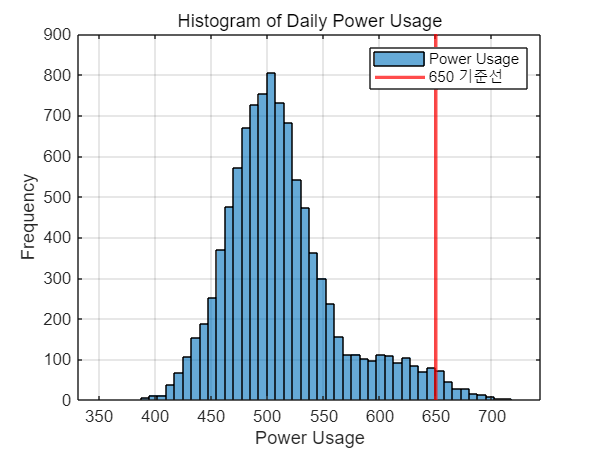


%% (e) 전체 전력 사용량 histogram
figure;
histogram(power_usage, 50);
grid on;
hold on;

xline(limit_power, 'r', 'LineWidth', 2);

title('Histogram of Daily Power Usage');
xlabel('Power Usage');
ylabel('Frequency');

legend('Power Usage', '650 기준선');


%% 과부하 발생일과 비발생일의 평균 전력 사용량 계산
mean_overload = mean(power_usage(cooling_overload));
mean_normal = mean(power_usage(~cooling_overload));

fprintf('과부하 발생일 평균 전력 사용량 = %.4f\n', mean_overload);

과부하 발생일 평균 전력 사용량 = 619.1846


fprintf('과부하 비발생일 평균 전력 사용량 = %.4f\n', mean_normal);

과부하 비발생일 평균 전력 사용량 = 499.8109
